# MATLAB Optimization Project

Traveling Salesman problem 10 cities

%clc;close; clear all;

figure(1)
Cities=[6.6, 7.1; 0.4, 0.3; 8.5, 2.8; 9.3, 0.5; 6.8, 1.0; 7.6, 8.2; 7.4, 6.9; 3.9, 3.4; 6.6, 9.5; 1.7, 0.3]

Cities =     6.6000    7.1000
    0.4000    0.3000
    8.5000    2.8000
    9.3000    0.5000
    6.8000    1.0000
    7.6000    8.2000
    7.4000    6.9000
    3.9000    3.4000
    6.6000    9.5000
    1.7000    0.3000


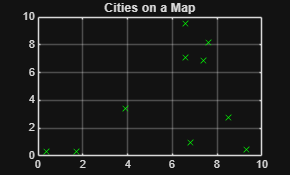

plot(Cities(:,1),Cities(:,2), 'xg')
xlim([0,10])
ylim([0,10])
grid on
title('Cities on a Map')

2 City test

function ds = EOMs(~,s,r)
    % s=[x, y, v, theta, LamX, LamY, LamV, LamTheta
    
    a = -r*s(7)/2;
    if abs(a)>1
        a=sign(a);
    end
    
    gamma = -r*s(8)/2;
    if abs(gamma)>1
        gamma=sign(gamma);
    end
   %state derrivitives 
    ds(1,1) = s(3)*cos(s(4)); % x_dot
    ds(2,1) = s(3)*sin(s(4)); % y_dot
    ds(3,1) = a; %v_dot
    ds(4,1) = gamma; %theta_dot

   %Costate derrivitives
    ds(5,1) = 0; %LamX_dot
    ds(6,1) = 0; %Lamy_dot
    ds(7,1) = -( s(5) * cos(s(4)) + s(6) * sin(s(4)) ); %LamV_dot
    ds(8,1) = -( s(3) * (-1 * s(5) * sin(s(4)) + s(6) * cos(s(4))) ); %LamTheta_dot
end

All Hail the Homotopy Constant:

r = 2;
fprintf('Homotopy Constant: %d', r);

Homotopy Constant: 2

theta_0 = 215;
guess =  [10, 10, 0, deg2rad(theta_0), 0.1 , 0.1 , -.8  , 0] 

guess =    10.0000   10.0000         0    3.7525    0.1000    0.1000   -0.8000         0


%initial:[x , y , v, heading         , lamX, LamY, LamV, LamTheta]

figure(2)
plot(Cities(:,1),Cities(:,2), 'xg') %plotting the origional cities
hold on
[T1, S1] = ode45( @(t,s)EOMs(t,s,r) , 0:0.1:2.4 , guess);
plot(S1(:,1),S1(:,2), '-y')


[T2, S2] = ode45( @(t,s)EOMs(t,s,r) , 2.4:0.1:3 , [S1(end,1:4), -2, -4, S1(end,7:8)]);
plot(S2(:,1),S2(:,2),'-r')

Taking the guess/... and ***Optimizing*** it.

solinit.x = linspace(0,1,11);
arc1 = interp1( T1/T1(end) , S1 , solinit.x );
arc2 = interp1( (T2-T1(end)) / (T2(end)-T1(end)) , S2 , solinit.x);

solinit.y = [arc1, arc2]'; %transpose the concatination of arc1 and arc2
fprintf('Size of Solinit.y is a: [%d, %d] matrix', size(solinit.y) )

Size of Solinit.y is a: [16, 11] matrix

solinit.parameters = [T1(end), T2(end)-T1(end)];

function ds = ELEOMs(t,s,p,r)
    ds(1:8,  1) = EOMs(t, s(1:8), r) * p(1);
    ds(9:16, 1) = EOMs(t, s(9:16), r) * p(2);
end

function constraint = bcfunc(si, sf, ~, r, Cities)
    %initial time (departure from depot)
    constraint(1,1) = si(1) - 10;
    constraint(2,1) = si(2) - 10;
    constraint(3,1) = si(3);
    constraint(4,1) = si(8);

    %intermediate time (arrival at city 1)
    constraint(5,1) = sf(1) - Cities(6,1); %x position of city 1
    constraint(6,1) = sf(2) - Cities(6,2); %y position of city 1
    constraint(7:10,1) = sf(1:4)-si(9:12); % x, y, v, & theta are continuous through intermediate time 
    constraint(11:12,1) = sf(7:8) - si(15:16); %only velocity and heading are unknown so costates are not 0 at intermediate time 
    a1 = max(-1, min(1, -r*sf(7)/2));
    gamma1 = max(-1, min(1, -r*sf(8)/2));
    
    constraint(13,1) = 1 + (1/r)*(a1^2+gamma1^2) + sf(5)*sf(3)*cos(sf(4)) + sf(6)*sf(3)*sin(sf(4))+ sf(7)*a1 + sf(8)*gamma1; %transversality condition (input H as its = 0) 
    
    %final time (arrival at city 2)
    constraint(14,1) = sf(9) - Cities(7,1); %x position of city 2
    constraint(15,1) = sf(10) - Cities(7,2); %y position of city 2
    constraint(16,1) = sf(15); %lamV active because velocity through city 2 is unknown
    constraint(17,1) = sf(16); %LamTheta active because heading through city 2 is unknown 
    a2 = max(-1, min(1, -r*sf(15)/2));
    gamma2 = max(-1, min(1, -r*sf(16)/2));
    
    constraint(18,1) = 1 + (1/r)*(a2^2+gamma2^2) + sf(13)*sf(11)*cos(sf(12)) + sf(14)*sf(11)*sin(sf(12)) + sf(15)*a2 + sf(16)*gamma2;
end

sol = bvp4c( @(t,s,p)ELEOMs(t, s, p, r), @(si, sf, p)bcfunc(si, sf, p, r, Cities), solinit);

fprintf('Soluition Converged! \nArc durration: %.4f, and %.4f seconds \nTotal time: %.4f', sol.parameters(1), sol.parameters(2), sum(sol.parameters(:,1)) );

Soluition Converged! 
Arc durration: 2.6455, and 0.6581 seconds 
Total time: 3.3036

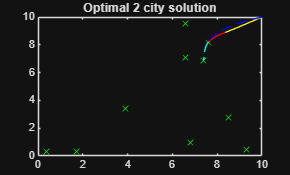


plot(sol.y(1,:),sol.y(2,:), '--b')
plot(sol.y(9,:),sol.y(10,:), '--c')
title('Optimal 2 city solution')
hold off

## Okay, since 2 cities clearly went SO well and was SOOOOOOOO easy to get going. Lets start to scale!

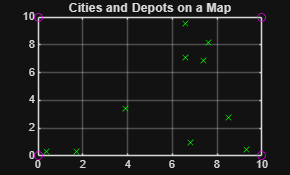

%clc; close all; clear;

figure(2)
Depots = [0, 0; 10, 0; 0, 10; 10, 10];
i = size(Cities, 1); % Number of cities (10)

plot(Cities(:,1), Cities(:,2), 'xg')
hold on
plot(Depots(:,1), Depots(:,2), 'om')
xlim([0, 10])
ylim([0, 10])
grid on
title('Cities and Depots on a Map')
hold off

### An ungodly amount of for loops to find the best order of cities to solve

function [best_depot, best_tour, best_score] = bruteforce_them_all_computationally_its_fine_mex(Cities, Depots, turn_weight)
    %BRUTFORCE_TSP_MEX Evaluates all (Depots*i!) routes via compiled C++ MEX.
    narginchk(3, 3);
    validateattributes(Cities,      {'double'}, {'2d', 'size', [10, 2], 'real', 'finite'}, mfilename, 'Cities', 1);
    validateattributes(Depots,     {'double'}, {'2d', 'ncols', 2, 'real', 'finite'},      mfilename, 'Depots', 2);
    validateattributes(turn_weight, {'double'}, {'scalar', 'real', 'nonnegative', 'finite'}, mfilename, 'turn_weight', 3);

    build_dir = fileparts(mfilename('fullpath'));
    if isempty(build_dir) || contains(build_dir, 'LiveEditorEvaluationHelper')
        active_file = matlab.desktop.editor.getActiveFilename;
        if ~isempty(active_file)
            build_dir = fileparts(active_file);
        else
            build_dir = pwd;
        end
    end

    if ~strcmp(build_dir, pwd)
        addpath(build_dir);
    end

    mex_name = 'bruteforce_them_all_computationally_its_fine_nested_cpp';
    mex_file = fullfile(build_dir, [mex_name, '.', mexext]);
    if exist(mex_file, 'file') ~= 3
        cpp_file = fullfile(build_dir, [mex_name, '.cpp']);
        fid = fopen(cpp_file, 'w');
        assert(fid ~= -1, 'Failed to create C++ source file in %s.', build_dir);
        fwrite(fid, get_nested_cpp_source());
        fclose(fid);

        fprintf('Compiling %s.cpp with MATLAB built-in C++ compiler...\n', mex_name);
        mex('-O', '-outdir', build_dir, cpp_file);
    end

    [best_depot, best_tour, best_score] = feval(mex_name, Cities, Depots, turn_weight);
end

function code = get_nested_cpp_source()
    % Returns the complete C++ MEX source code as a single newline-joined string, alll oneeee longggggggggggggggggggggggggggg lineeeeeeee
    code = strjoin({
        '#include "mex.h"'
        '#include <cmath>'
        ''
        '#ifndef M_PI'
        '#define M_PI 3.14159265358979323846'
        '#endif'
        ''
        'inline double wrap_angle(double dth) {'
        '    if (dth > M_PI)       dth -= 2.0 * M_PI;'
        '    else if (dth < -M_PI) dth += 2.0 * M_PI;'
        '    return dth;'
        '}'
        ''
        'void mexFunction(int nlhs, mxArray* plhs[], int nrhs, const mxArray* prhs[])'
        '{'
        '    if (nrhs != 3) mexErrMsgIdAndTxt("TSP:nrhs", "Expected 3 inputs.");'
        ''
        '    int M = (int)mxGetM(prhs[0]);'
        '    int C = (int)mxGetM(prhs[1]);'
        '    if (M != 10) mexErrMsgIdAndTxt("TSP:size", "Expected M = 10 cities.");'
        ''
        '    const double* cx = mxGetPr(prhs[0]);'
        '    const double* cy = cx + M;'
        '    const double* kx = mxGetPr(prhs[1]);'
        '    const double* ky = kx + C;'
        '    double w_turn = mxGetScalar(prhs[2]);'
        ''
        '    double d_start[4][10], th_start[4][10];'
        '    double d_city[10][10], th_city[10][10];'
        ''
        '    for (int c = 0; c < C; ++c) {'
        '        for (int j = 0; j < 10; ++j) {'
        '            double dx = cx[j] - kx[c];'
        '            double dy = cy[j] - ky[c];'
        '            d_start[c][j]  = std::hypot(dx, dy);'
        '            th_start[c][j] = std::atan2(dy, dx);'
        '        }'
        '    }'
        ''
        '    for (int i = 0; i < 10; ++i) {'
        '        for (int j = 0; j < 10; ++j) {'
        '            double dx = cx[j] - cx[i];'
        '            double dy = cy[j] - cy[i];'
        '            d_city[i][j]  = std::hypot(dx, dy);'
        '            th_city[i][j] = std::atan2(dy, dx);'
        '        }'
        '    }'
        ''
        '    double best_cost = INFINITY;'
        '    int best_corner = 0;'
        '    int best_order[10] = {0};'
        '    bool visited[10] = {false};'
        ''
        '    for (int c = 0; c < C; ++c) {'
        '        for (int c1 = 0; c1 < 10; ++c1) {'
        '            double th1   = th_start[c][c1];'
        '            double cost1 = d_start[c][c1];'
        '            if (cost1 >= best_cost) continue;'
        '            visited[c1] = true;'
        ''
        '            for (int c2 = 0; c2 < 10; ++c2) {'
        '                if (visited[c2]) continue;'
        '                double th2   = th_city[c1][c2];'
        '                double cost2 = cost1 + d_city[c1][c2] + w_turn * std::fabs(wrap_angle(th2 - th1));'
        '                if (cost2 >= best_cost) continue;'
        '                visited[c2] = true;'
        ''
        '                for (int c3 = 0; c3 < 10; ++c3) {'
        '                    if (visited[c3]) continue;'
        '                    double th3   = th_city[c2][c3];'
        '                    double cost3 = cost2 + d_city[c2][c3] + w_turn * std::fabs(wrap_angle(th3 - th2));'
        '                    if (cost3 >= best_cost) continue;'
        '                    visited[c3] = true;'
        ''
        '                    for (int c4 = 0; c4 < 10; ++c4) {'
        '                        if (visited[c4]) continue;'
        '                        double th4   = th_city[c3][c4];'
        '                        double cost4 = cost3 + d_city[c3][c4] + w_turn * std::fabs(wrap_angle(th4 - th3));'
        '                        if (cost4 >= best_cost) continue;'
        '                        visited[c4] = true;'
        ''
        '                        for (int c5 = 0; c5 < 10; ++c5) {'
        '                            if (visited[c5]) continue;'
        '                            double th5   = th_city[c4][c5];'
        '                            double cost5 = cost4 + d_city[c4][c5] + w_turn * std::fabs(wrap_angle(th5 - th4));'
        '                            if (cost5 >= best_cost) continue;'
        '                            visited[c5] = true;'
        ''
        '                            for (int c6 = 0; c6 < 10; ++c6) {'
        '                                if (visited[c6]) continue;'
        '                                double th6   = th_city[c5][c6];'
        '                                double cost6 = cost5 + d_city[c5][c6] + w_turn * std::fabs(wrap_angle(th6 - th5));'
        '                                if (cost6 >= best_cost) continue;'
        '                                visited[c6] = true;'
        ''
        '                                for (int c7 = 0; c7 < 10; ++c7) {'
        '                                    if (visited[c7]) continue;'
        '                                    double th7   = th_city[c6][c7];'
        '                                    double cost7 = cost6 + d_city[c6][c7] + w_turn * std::fabs(wrap_angle(th7 - th6));'
        '                                    if (cost7 >= best_cost) continue;'
        '                                    visited[c7] = true;'
        ''
        '                                    for (int c8 = 0; c8 < 10; ++c8) {'
        '                                        if (visited[c8]) continue;'
        '                                        double th8   = th_city[c7][c8];'
        '                                        double cost8 = cost7 + d_city[c7][c8] + w_turn * std::fabs(wrap_angle(th8 - th7));'
        '                                        if (cost8 >= best_cost) continue;'
        '                                        visited[c8] = true;'
        ''
        '                                        for (int c9 = 0; c9 < 10; ++c9) {'
        '                                            if (visited[c9]) continue;'
        '                                            double th9   = th_city[c8][c9];'
        '                                            double cost9 = cost8 + d_city[c8][c9] + w_turn * std::fabs(wrap_angle(th9 - th8));'
        '                                            if (cost9 >= best_cost) continue;'
        '                                            visited[c9] = true;'
        ''
        '                                            for (int c10 = 0; c10 < 10; ++c10) {'
        '                                                if (visited[c10]) continue;'
        '                                                double th10   = th_city[c9][c10];'
        '                                                double cost10 = cost9 + d_city[c9][c10] + w_turn * std::fabs(wrap_angle(th10 - th9));'
        '                                                if (cost10 < best_cost) {'
        '                                                    best_cost   = cost10;'
        '                                                    best_corner = c;'
        '                                                    best_order[0] = c1; best_order[1] = c2; best_order[2] = c3;'
        '                                                    best_order[3] = c4; best_order[4] = c5; best_order[5] = c6;'
        '                                                    best_order[6] = c7; best_order[7] = c8; best_order[8] = c9;'
        '                                                    best_order[9] = c10;'
        '                                                }'
        '                                            }'
        '                                            visited[c9] = false;'
        '                                        }'
        '                                        visited[c8] = false;'
        '                                    }'
        '                                    visited[c7] = false;'
        '                                }'
        '                                visited[c6] = false;'
        '                            }'
        '                            visited[c5] = false;'
        '                        }'
        '                        visited[c4] = false;'
        '                    }'
        '                    visited[c3] = false;'
        '                }'
        '                visited[c2] = false;'
        '            }'
        '            visited[c1] = false;'
        '        }'
        '    }'
        ''
        '    plhs[0] = mxCreateDoubleScalar((double)(best_corner + 1));'
        '    plhs[1] = mxCreateDoubleMatrix(1, M, mxREAL);'
        '    plhs[2] = mxCreateDoubleScalar(1000.0 / best_cost);'
        ''
        '    double* out_tour = mxGetPr(plhs[1]);'
        '    for (int i = 0; i < M; ++i) out_tour[i] = (double)(best_order[i] + 1);'
        '}'
    }, newline);
end

turn_weight = 0.5; % Penalty weight on sharp heading changes (0 = no penalty) increment as solutions are found to develop sensitivity of solution to euclidian distance
tic;

[best_depots_idx, tour, best_score] = bruteforce_them_all_computationally_its_fine_mex(Cities, Depots, turn_weight);
elapsed_mex = toc;

Departure = Depots(best_depots_idx, :);
OrderedCities = Cities(tour, :);

fprintf('Checked %d Combinations via C++ MEX in %.4f s!\n', size(Depots, 1) * factorial(i), elapsed_mex);

Checked 14515200 Combinations via C++ MEX in 0.1127 s!


fprintf('Highest-Scoring Start Corner: [%d, %d] | Winning Score: %.4f\n', Departure(1), Departure(2), best_score);

Highest-Scoring Start Corner: [0, 0] | Winning Score: 36.0194


fprintf('Optimal City Order: %s\n', num2str(tour));

Optimal City Order: 2  10   8   5   4   3   7   1   6   9


#### Well, now that we've used MEX to brute force all of those permutations to find the lowest total score through all 10 cities... ***Optimize*** the arcs!

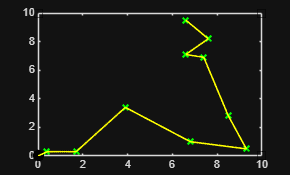

function ds = dynEOMs(~, s, r)
    % s = [x, y, v, theta, LamX, LamY, LamV, LamTheta]
    a = -r * s(7) / 2;
    if abs(a) > 1
        a = sign(a);
    end

    gamma = -r * s(8) / 2;
    if abs(gamma) > 1
        gamma = sign(gamma);
    end

    % State derivatives
    ds(1,1) = s(3) * cos(s(4)); % x_dot
    ds(2,1) = s(3) * sin(s(4)); % y_dot
    ds(3,1) = a; % v_dot
    ds(4,1) = gamma; % theta_dot

    % Costate derivatives
    ds(5,1) = 0; % LamX_dot
    ds(6,1) = 0; % LamY_dot
    ds(7,1) = -(s(5) * cos(s(4)) + s(6) * sin(s(4))); % LamV_dot
    ds(8,1) = -(s(3) * (-1 * s(5) * sin(s(4)) + s(6) * cos(s(4)))); % LamTheta_dot
end

figure(2)
plot(Cities(:,1), Cities(:,2), 'xg', 'LineWidth', 1.5)
hold on
plot(Depots(:,1), Depots(:,2), 'ks', 'MarkerSize', 8)
plot(Departure(1), Departure(2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8)

N_mesh = 15;
r_list = logspace(log10(0.02), log10(50), 30); % 30 smooth steps from unsaturated (0.02) to bang-bang (50)
r0     = r_list(1);

solinit.x = linspace(0, 1, N_mesh);
solinit.y = zeros(8 * i, N_mesh);
solinit.parameters = zeros(1, i);

OrderedPath = [Departure; OrderedCities];
v_cruise    = 0.8; % Keeps short first leg [0,0]->[0.4,0.3] well below a = 1 saturation
theta_start = atan2(OrderedPath(2,2) - OrderedPath(1,2), OrderedPath(2,1) - OrderedPath(1,1));

for k = 1:i
    P1 = OrderedPath(k, :);
    P2 = OrderedPath(k + 1, :);

    % Wrap heading change into [-pi, pi]
    raw_theta = atan2(P2(2) - P1(2), P2(1) - P1(1));
    d_theta   = atan2(sin(raw_theta - theta_start), cos(raw_theta - theta_start));
    theta_end = theta_start + d_theta;

    dist_k = norm(P2 - P1);
    dt_k   = max([dist_k / v_cruise, abs(d_theta) / 0.6 + 0.5, 1.0]);

    if k == 1
        v_start = 0; % Starts from rest at winning corner depot
    else
        v_start = v_cruise;
    end

    % Physically consistent control & costate guesses scaled to r0
    a_guess     = (v_cruise - v_start) / dt_k;
    gamma_guess = d_theta / dt_k;

    x_g     = linspace(P1(1), P2(1), N_mesh);
    y_g     = linspace(P1(2), P2(2), N_mesh);
    v_g     = linspace(v_start, v_cruise, N_mesh);
    theta_g = linspace(theta_start, theta_end, N_mesh);

    % Non-zero costate ramps avoiding zero-derivative flat spots and saturation walls
    LamV_g     = linspace(-2 * a_guess / r0 - 0.1, -0.05, N_mesh);
    LamTheta_g = (-2 * gamma_guess / r0 + 0.05) * ones(1, N_mesh);

    % Scale (LamX, LamY) so H(tk-) ≈ 0 at the end of each arc
    H_rem  = 1 + (1/r0)*(a_guess^2 + gamma_guess^2) + LamV_g(end)*v_cruise + LamTheta_g(end)*gamma_guess;
    lam_xy = max(0.5, H_rem / v_cruise);
    LamX_g = -lam_xy * cos(theta_end) * ones(1, N_mesh);
    LamY_g = -lam_xy * sin(theta_end) * ones(1, N_mesh);

    idx = (k - 1)*8 + (1:8);
    solinit.y(idx, :)     = [x_g; y_g; v_g; theta_g; LamX_g; LamY_g; LamV_g; LamTheta_g];
    solinit.parameters(k) = dt_k;

    theta_start = theta_end;
    plot(x_g, y_g, '-y', 'LineWidth', 1.2)
end


fprintf('Size of Solinit.y is a: [%d, %d] matrix\n', size(solinit.y));

Size of Solinit.y is a: [80, 15] matrix



options = bvpset('RelTol', 1e-4, 'AbsTol', 1e-6, 'NMax', 5000, 'Stats', 'on');
sol     = solinit;

%% SOLVINGG FINALLY RAHHHHHHHHH
for ii = 1:length(r_list)
    r = r_list(ii);
    sol = bvp4c(@(t,s,p) dynELEOMs(t, s, p, r, i), @(si,sf,p) dynbcfunc(si, sf, p, r, OrderedCities, Departure), sol, options);
    fprintf('Homotopy Constant r = %6.3f Converged! | Total Time: %.4f s\n', r, sum(sol.parameters));
end

Error using bvp4c (line 196)
Unable to solve the collocation equations -- a singular Jacobian encountered.


function ds = dynELEOMs(t, s, p, r, i)
    ds = zeros(8 * i, 1);
    for k = 1:i
        idx = (k - 1)*8 + (1:8);
        ds(idx, 1) = dynEOMs(t, s(idx), r) * p(k);
    end
end

function constraint = dynbcfunc(si, sf, ~, r, OrderedCities, Departure)
    i = size(OrderedCities, 1);
    constraint = zeros(9 * i, 1);

    % Initial time (departure from winning corner depot)
    constraint(1,1) = si(1) - Departure(1);
    constraint(2,1) = si(2) - Departure(2);
    constraint(3,1) = si(3);
    constraint(4,1) = si(8);

    c = 5;
    % Intermediate times (arrival & continuity through cities 1 .. i-1)
    for k = 1:(i - 1)
        idx1 = (k - 1)*8 + (1:8);
        idx2 = k*8 + (1:8);

        constraint(c, 1)             = sf(idx1(1)) - OrderedCities(k, 1); % x position of city k
        constraint(c + 1, 1)         = sf(idx1(2)) - OrderedCities(k, 2); % y position of city k
        constraint(c + 2 : c + 5, 1) = sf(idx1(1:4)) - si(idx2(1:4));     % x, y, v, & theta continuous
        constraint(c + 6 : c + 7, 1) = sf(idx1(7:8)) - si(idx2(7:8));     % LamV & LamTheta continuous

        ak = max(-1, min(1, -r * sf(idx1(7)) / 2));
        gammak = max(-1, min(1, -r * sf(idx1(8)) / 2));
        constraint(c + 8, 1) = 1 + (1/r)*(ak^2 + gammak^2) + sf(idx1(5))*sf(idx1(3))*cos(sf(idx1(4))) + sf(idx1(6))*sf(idx1(3))*sin(sf(idx1(4))) + sf(idx1(7))*ak + sf(idx1(8))*gammak; % H(tk-) = 0

        c = c + 9;
    end

    % Final time (arrival at final city i)
    idxi = (i - 1)*8 + (1:8);
    constraint(c, 1)     = sf(idxi(1)) - OrderedCities(i, 1); % x position of city M
    constraint(c + 1, 1) = sf(idxi(2)) - OrderedCities(i, 2); % y position of city M
    constraint(c + 2, 1) = sf(idxi(7));                       % LamV active (final velocity unknown)
    constraint(c + 3, 1) = sf(idxi(8));                       % LamTheta active (final heading unknown)

    ai     = max(-1, min(1, -r * sf(idxi(7)) / 2));
    gammai = max(-1, min(1, -r * sf(idxi(8)) / 2));
    constraint(c + 4, 1) = 1 + (1/r)*(ai^2 + gammai^2) ...
                         + sf(idxi(5))*sf(idxi(3))*cos(sf(idxi(4))) ...
                         + sf(idxi(6))*sf(idxi(3))*sin(sf(idxi(4))) ...
                         + sf(idxi(7))*ai + sf(idxi(8))*gammai;           % H(tf) = 0
end

options = bvpset('RelTol', 1e-4, 'AbsTol', 1e-6, 'NMax', 5000);
r_list  = linspace(0.01, 50, 500);
sol     = solinit;

for ii = 1:length(r_list)
    r = r_list(ii);
    sol = bvp4c(@(t,s,p) dynELEOMs(t, s, p, r, i), @(si,sf,p) dynbcfunc(si, sf, p, r, OrderedCities, Departure), sol, options);
    fprintf('Homotopy Constant r = %5.2f Converged! | Total Time: %.4f s\n', r, sum(sol.parameters(:,1)));
end

fprintf('\nSolution Converged!\nArc durations: %s\nTotal time: %.4f seconds\n', ...
        num2str(sol.parameters, '%.4f  '), sum(sol.parameters));


Plotting on your success

for k = 1:i
    idx = (k - 1)*8 + (1:8);
    if mod(k, 2) == 1
        plot(sol.y(idx(1), :), sol.y(idx(2), :), '--b', 'LineWidth', 1.8)
    else
        plot(sol.y(idx(1), :), sol.y(idx(2), :), '--c', 'LineWidth', 1.8)
    end
    text(OrderedCities(k,1) + 0.15, OrderedCities(k,2) + 0.15, sprintf('#%d (C%d)', k, tour(k)))
end
xlim([0, 10.5])
ylim([0, 10.5])
grid on
title(['10-City Optimal Trajectory (Start [', num2str(Departure(1)), ',', num2str(Departure(2)), ...
       '], r = ', num2str(r), ', Total Time = ', num2str(sum(sol.parameters), '%.2f'), ' s)'])

% Stitch time, speed, and control arrays across all 10 arcs for plotting
t_full = []; v_full = []; a_full = []; g_full = [];
t_start = 0;
for k = 1:i
    idx = (k - 1)*8 + (1:8);
    t_k = t_start + sol.x * sol.parameters(k);
    a_k = max(-1, min(1, -r * sol.y(idx(7), :) / 2));
    g_k = max(-1, min(1, -r * sol.y(idx(8), :) / 2));

    t_full  = [t_full, t_k];
    v_full  = [v_full, sol.y(idx(3), :)];
    a_full  = [a_full, a_k];
    g_full  = [g_full, g_k];
    t_start = t_k(end);
end

figure(3)
subplot(3,1,1)
plot(t_full, v_full, '-b', 'LineWidth', 1.5)
grid on
ylabel('Speed v(t)')
title(['Optimal Speed & Controls (r = ', num2str(r), ')'])

subplot(3,1,2)
plot(t_full, a_full, '-r', 'LineWidth', 1.5)
grid on
ylabel('Accel a(t)')
ylim([-1.2, 1.2])

subplot(3,1,3)
plot(t_full, g_full, '-k', 'LineWidth', 1.5)
grid on
ylabel('Turn Rate \gamma(t)')
ylim([-1.2, 1.2])
xlabel('Time (s)')